image_path = "Images\W107b.jpg"

image_path = "Images\W107b.jpg"

Final_mask  = Segmentaion_Method(image_path)

Final_mask = 2048×2048 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   

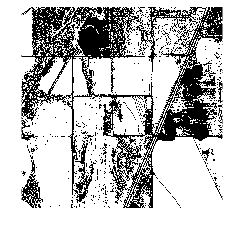

imshow(Final_mask)

imwrite(Final_mask,"Output_Image_without_forest_W107b.jpg")
img = imread(image_path)

img = 2048×2048×3 uint8 array
img(:,:,1) =

  Columns 1 through 1,666

   115   115   114   114   112   112   112   112   110   104    96    89    88    90    91    92    95   103   114   122   122   119   119   118   117   115   116   117   116   107    94    84    88    93    99   108   112   113   116   118   119   119   116   108   100    93    93    94   102   113   122   126   128   127   120   110   116   110   103   103   109   117   121   122   111   105   103   103   102   104   105   101    93    96   100   105   105   103   102   102    99    96    93    91    89    87    87    89    87    87    86    85    86    85    82    79    83    82    85   113   132   184   208   215   201   167   131   113   105    99    84    62    47    50    66    69    68    67    64    75    57    58    56    53    67    62    64    57    69    69    76    65    61    58    60    44    46    51    51    55    66    68    66    68    75    68    61    50    60    58    61    59    68    63    5

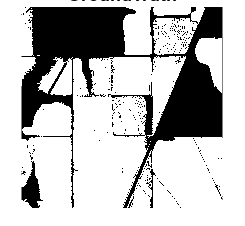

accuracy = 0.8169

precision = 0.8711

ConfusionMatrix =      1044041      415756
      352409     2382098


imwrite(img.*uint8(Final_mask),"mask_applied_Image_without_forest_W107b.jpg")
[accuracy,precision,ConfusionMatrix] = Evaluvation(image_path,Final_mask)

accuracy

accuracy = 0.8169

precision

precision = 0.8711

ConfusionMatrix

ConfusionMatrix =      1044041      415756
      352409     2382098


function mask = K_Means(image_path)
    img = imread(image_path);
    
    numColors=2;
    lab_he = rgb2lab(img);
    ab = lab_he(:,:,2:2);
    ab = im2single(ab);
    pixel_labels = imsegkmeans(ab,numColors,NumAttempts=2);
    mask1 = pixel_labels == 2;
    mask2 = pixel_labels ~= 1;
    mask = mask1 | mask2;
    
    numberOfZeros = numel(mask) - nnz(mask);
    if numberOfZeros>nnz(mask)
        mask = ~mask;
    end
          
end
function Final_mask =  Segmentaion_Method(image_path)
    I = imread(image_path);
    mask = K_Means(image_path);
    I = rgb2gray(I);
    se = strel('disk',5);
    background = imopen(I,se);
    %imshow(background)
    I2 = I - background;
    I3 = imadjust(I2);
    %imshow(I3)
    bw = imbinarize(I3);
    bw = bwareaopen(bw,50);
    Final_mask = ~bw&mask;
    %imwrite(background,"morph_T.jpg")
    %imwrite(I2,"sub_back.jpg")
    %imwrite(I3,"adjust_con.jpg")
    %imwrite(bw,"binarize.jpg")
    %imwrite(~bw,"inverted.jpg")
    %imwrite(Final_mask,"Final_mask.jpg")
    
end
function [accuracy,precision,ConfusionMatrix] = Evaluvation(image_path,mask)
    gt_path  = "Ground_Truths_without_forest\Ground_truth_without_forest_";
    image_file = split(image_path,"\");
    gt_path = strcat(gt_path,image_file(2));
    gt = imread(gt_path);
    bw = imbinarize(gt);
    imshow(bw)
    title("GroundTruth")
    C = segmentationConfusionMatrix(mask,bw);
    accuracy = (C(1,1)+C(2,2))/(C(1,1)+C(1,2)+C(2,1)+C(2,2));
    precision = (C(2,2))/(C(2,1)+C(2,2));
    ConfusionMatrix = C;
end